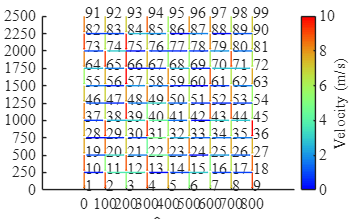

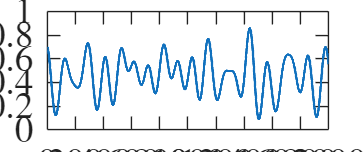

new_path = 1

    10    11    12    13    14    15    16    17    18    27    36    45    54    63    72    81    90



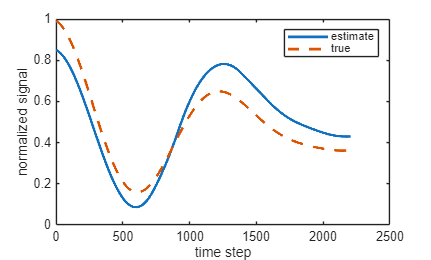

new_path = 2

    10    19    20    21    22    23    24    25    26    35    44    53    62    71    80    89    90



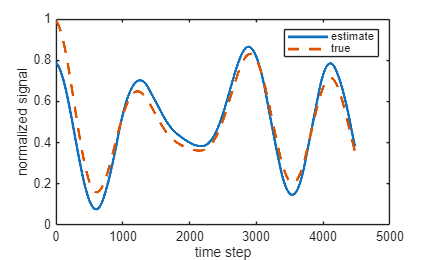

new_path = 3

    10    11    20    29    30    31    32    33    34    43    52    61    70    79    88    89    90



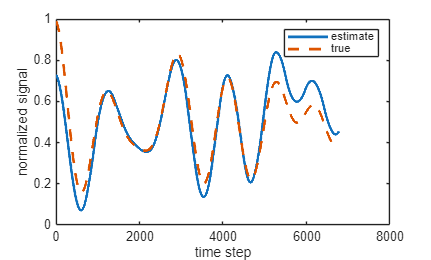

new_path = 4

    10    11    12    21    30    39    40    41    42    51    60    69    78    87    88    89    90



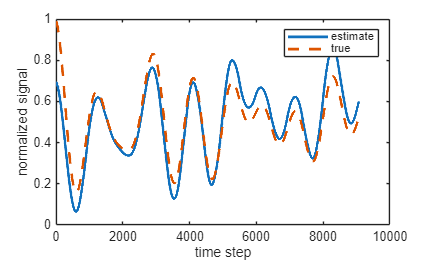

new_path = 5

    10    11    12    13    22    31    40    49    50    59    68    77    86    87    88    89    90



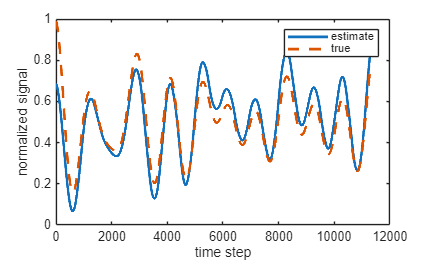

new_path = 6

    10    11    12    13    14    23    32    41    50    49    58    67    76    85    86    87    88    89    90



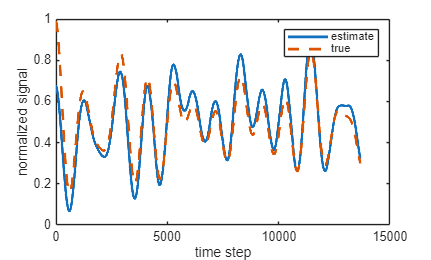

new_path = 7

    10    11    20    19    28    29    38    39    48    57    66    75    84    85    86    87    88    89    90



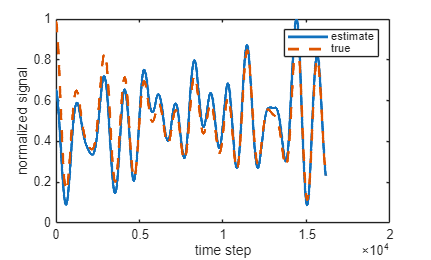

new_path = 8

    10    11    20    19    28    37    38    47    56    65    74    83    84    85    86    87    88    89    90



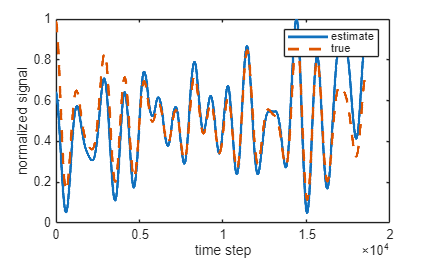

new_path = 9

    10    11    20    19    28    37    46    55    64    73    82    83    84    85    86    87    88    89    90



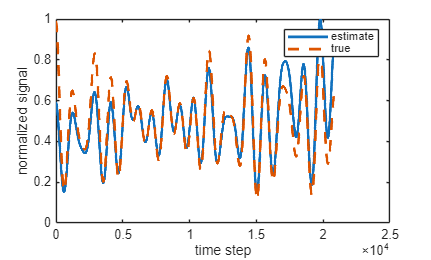

new_path = 10

    10    11    12    13    14    15    24    33    42    51    60    69    78    79    80    81    90



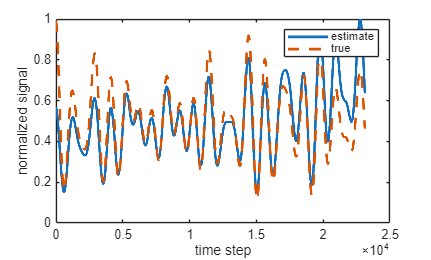

new_path = 11

    10    11    12    13    14    15    16    25    34    33    42    51    60    69    70    71    72    81    90



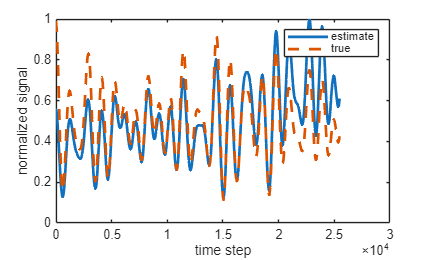

new_path = 12

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



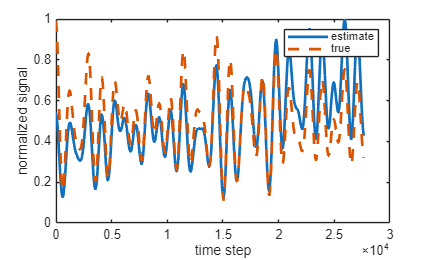

same_path = 13

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



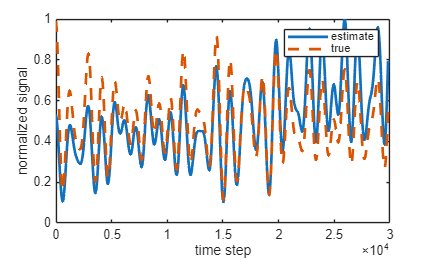

same_path = 14

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



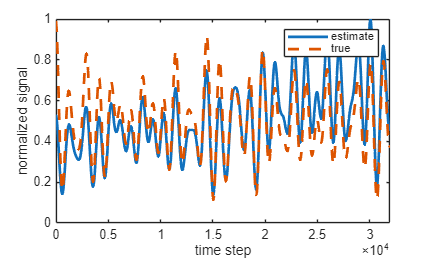

same_path = 15

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



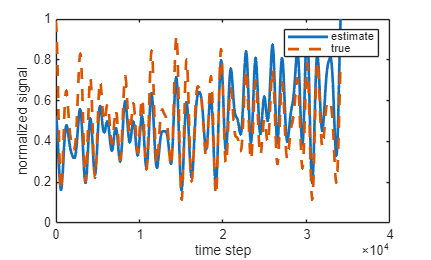

same_path = 16

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



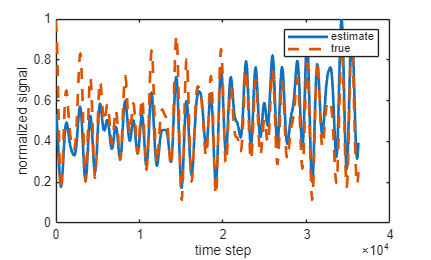

same_path = 17

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



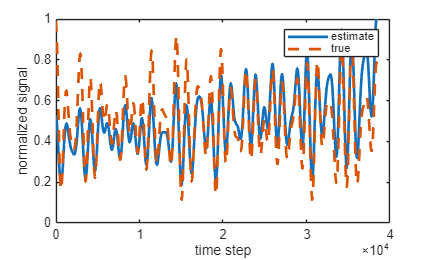

same_path = 18

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



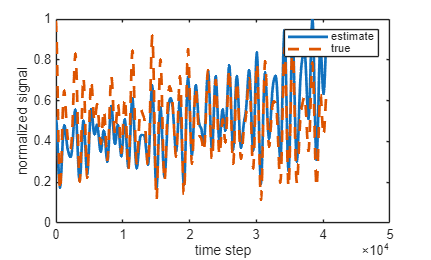

same_path = 19

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



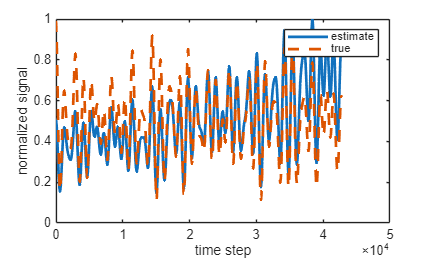

same_path = 20

    10    11    20    21    22    31    32    41    42    51    60    69    78    79    80    81    90



%% Standard License Agreement
%{
SOFTWARE LICENSE
----------------
Copyright (c) 2026 by 
	Jeffrey DesRoches
	Raghvendra Cowlagi

Permission is hereby granted to any person obtaining a copy of this
software and associated documentation files (the "Software"), to deal in
the Software, including the rights to use, copy, modify, merge, copies of
the Software, and to permit persons to whom the Software is furnished to do
so, subject to the following conditions:  

* The above copyright notice and this permission notice shall be included
in all copies or substantial portions of the Software.
* The Software, and its copies or modifications, may not be distributed,
published, or sold for profit. 
* The Software, and any substantial portion thereof, may not be copied or
modified for commercial or for-profit use.

The software is provided "as is", without warranty of any kind, express or
implied, including but not limited to the warranties of merchantability,
fitness for a particular purpose and noninfringement. In no event shall the
authors or copyright holders be liable for any claim, damages or other
liability, whether in an action of contract, tort or otherwise, arising
from, out of or in connection with the software or the use or other
dealings in the software.      


PROGRAM DESCRIPTION
-------------------
Sequential Path Planning in an Unknown Urban Wind Field
This script evaluates a centralized agent that repeatedly plans and
traverses minimum-time paths through a simulated urban wind field while
updating its edge-wind estimates from measurements collected along the
traversed routes.

In the paper, this script serves as the main experiment driver for:
1) generating the urban graph and wind field,
2) simulating repeated path traversal,
3) reconstructing the latent wind-driving signal from edge measurements,
4) updating directed edge-wind estimates, and
5) comparing estimated and realized path costs across successive passes.
%}

clc; clear; close all;

s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = 'light';

%% Problem setup
grid_rc   = [7,5];           % [rows, cols] in the urban graph representation
W_max     = 10;              % maximum wind magnitude used in the simulation (m/s)
U_ego     = 15;              % constant vehicle airspeed (m/s)
U_ego_min = U_ego - W_max;   % conservative lower bound used for preallocation

% Generate graph geometry, edge lengths, directed wind gains, and terminal nodes.
[x_node, L_ij, rho_true_ij, v_goal, v_start, N_nodes, A_ij] = citymap(grid_rc, W_max);

% Visualize the true wind field over the graph.
plotwindfield(N_nodes, x_node, tril(rho_true_ij), W_max);

%% Wind signal generation
dt        = 0.1;        % simulation time step (s)
finaltime = 20000;      % total simulated time horizon (s)
period    = 200;        % nominal temporal period of the wind-driving signal (s)
rseed     = 42;         % random seed for repeatability
aperiodic = [];         % optional aperiodic component

% Generate the latent temporal driver used in the wind field simulation.
[dP_true_noise, phi, t, dP_true_clean, ~, ~, ~] = ...
    windgen(rseed, period, finaltime, dt, 6, aperiodic, 3, 0, 0.025);

%% Main experiment loop
% Number of repeated planning/traversal passes.
numsims = 20;

% Conservative storage bounds for all traversed edges and samples.
maxEdgesPerPass = (grid_rc(1)-2) * grid_rc(2);
maxEdgesTotal   = numsims * maxEdgesPerPass;
maxStepsPerEdge = ceil(max(L_ij(:)) / (U_ego_min * dt)) + 1;

% Concatenated storage for fitted edge signals used during stitching.
z_edge_hist = zeros(1, maxEdgesTotal * maxStepsPerEdge);
z_raw_hist  = [];
z_hist_ptr  = 1;

% Initialize the edge-cost estimate with an optimistic prior that promotes exploration.
c_hat_ij = L_ij / (U_ego + W_max);

% Remove non-traversable boundary entries from the working cost matrix.
c_hat_ij(1:grid_rc(2), :) = 0;
c_hat_ij(end-grid_rc(2)+1:end, :) = 0;
c_hat_ij(:, 1:grid_rc(2)) = 0;
c_hat_ij(:, end-grid_rc(2)+1:end) = 0;
rho_true_ij(c_hat_ij == 0) = 0;

% Initialize directed edge-wind estimates on traversable edges only.
rho_hat_ij             = zeros(size(c_hat_ij));
mask_edges             = (c_hat_ij ~= 0);
rho_hat_ij(mask_edges) = W_max;

% Store the pass-initial prior so the full estimate can be rebuilt after each pass.
rho_init_ij = rho_hat_ij;

% Diagnostics for edge-wind estimation error over passes.
rho_diff_hist     = cell(1, numsims+1);
rho_diff_hist{1}  = rho_hat_ij - rho_true_ij;
rho_err_max_pass  = nan(1, numsims);
rho_err_min_pass  = nan(1, numsims);
rho_err_mean_pass = nan(1, numsims);
rho_err_var_pass  = nan(1, numsims);

% Shared metric storage used by downstream routines.
global metrics metric_count

path_nodes        = zeros((grid_rc(1)-2) * grid_rc(2), numsims);
J_pass            = zeros(1, numsims);   % realized path cost
J_hat_pass        = zeros(1, numsims);   % predicted path cost

t_idx        = 1;
dP_hat       = [];
metrics      = zeros(7, numsims * (grid_rc(1) + grid_rc(2) - 4));
metric_count = 1;

% Parameters used to reconstruct the latent driving signal from edge segments.
beta_f   = [];
gamma_f  = [];
lambda_b = [];

% Global statistics of the reconstructed signal used in trust weighting.
dP_mu_global    = 0.5;
dP_sigma_global = 0.1;

done = 0;

for j = 1:numsims

    % Record the metric index at the beginning of the current pass.
    k_start_pass = metric_count; 

    % Compute the current minimum-cost path using the latest cost estimate.
    [path_j, path_nodes, J_hat_pass] = Dijkstra( ...
        N_nodes, c_hat_ij, j, path_nodes, J_hat_pass, v_start, v_goal);

    % Display the current path for traceability across passes.
    if j > 1 && any(path_nodes(:,j) ~= path_nodes(:,j-1))
        new_path = j
        disp(path_j')
    elseif j == 1
        new_path = j
        disp(path_j')
    else
        same_path = j
        disp(path_j')
    end

    %% Traverse each edge on the selected path
    for i = 1:length(path_j)-1

        dist_accum = 0;
        i_idx      = path_j(i);
        j_idx      = path_j(i+1);
        L_e        = L_ij(i_idx, j_idx);
        rho_true_e = rho_true_ij(i_idx, j_idx);
        maxPtsEdge = ceil(L_e / (U_ego_min * dt)) + 1;

        z_edge_meas = zeros(1, maxPtsEdge);
        k_e         = 0;
        dt_edge     = 0;

        % Simulate motion along the current edge and collect wind measurements.
        while dist_accum < L_e
            k_e = k_e + 1;

            baseWind = dP_true_clean(t_idx) * cos(phi(t_idx)) * rho_true_e;

            % For length-250 edges, only the nominal along-edge contribution is used.
            % Otherwise, an additional crosswind contribution is included.
            if L_e == 250
                z_edge_meas(k_e) = baseWind;
                dist_accum = dist_accum + ...
                    (U_ego + dP_true_noise(t_idx) * cos(phi(t_idx)) * rho_true_e) * dt;
            else
                cw = crosswind(A_ij, rho_true_ij, dP_true_clean(t_idx), phi(t_idx), grid_rc);
                z_edge_meas(k_e) = baseWind + cw;

                cw_true = crosswind(A_ij, rho_true_ij, dP_true_noise(t_idx), phi(t_idx), grid_rc);
                dist_accum = dist_accum + ...
                    (U_ego + dP_true_noise(t_idx) * cos(phi(t_idx)) * rho_true_e + cw_true) * dt;
            end

            t_idx   = t_idx + 1;
            dt_edge = dt_edge + dt;
        end

        % Retain only the samples generated before the edge traversal completed.
        z_edge_meas = z_edge_meas(1:k_e);
        z_raw_hist  = [z_raw_hist, z_edge_meas];
        vel_length  = k_e;
        metrics(6, metric_count) = vel_length;

        % Accumulate realized traversal time for the current pass.
        J_pass(j) = J_pass(j) + dt_edge;

        % Stop after the final edge of the final pass.
        if j == numsims && i == length(path_j)-1
            done = 1;
            break
        end

        %% Fit a local edge model for subsequent signal stitching
        [p, ~, mu] = polyfit(1:vel_length, z_edge_meas, 2);
        z_edge_fit = polyval(p, [0.5, 1:vel_length, vel_length+0.5], [], mu);

        % Residual variance provides a simple edge-level noise proxy.
        residual_edge          = z_edge_meas - z_edge_fit(2:end-1);
        q_std_hat              = sqrt(max(eps, sum(residual_edge.^2) / max(1, (vel_length - 3))));
        metrics(7, metric_count) = q_std_hat^2;

        % Append the fitted segment, including end caps, to the global stitching tape.
        n = length(z_edge_fit);
        z_edge_hist(z_hist_ptr:z_hist_ptr+n-1) = z_edge_fit;
        z_hist_ptr = z_hist_ptr + n;

        %% Reconstruct the latent driving signal at the end of each pass
        if j == 1 && i == 1
            beta_0   = 0.5;
            gamma_0  = 0;
            lambda_0 = 0;
        else
            if i == 1
                beta_0   = [beta_f;   0.5];
                gamma_0  = [gamma_f;  0];
                lambda_0 = [lambda_b; 0];
            elseif i < length(path_j)-1
                beta_0   = [beta_0;   0.5];
                gamma_0  = [gamma_0;  0];
                lambda_0 = [lambda_0; 0];
            else
                beta_0   = [beta_0;   0.5];
                gamma_0  = [gamma_0;  0];
                lambda_0 = [lambda_0; 0];

                options = optimoptions('fmincon', ...
                    'Algorithm', 'interior-point', ...
                    'MaxFunctionEvaluations', 10e4, ...
                    'Display', 'off');

                x_0 = [beta_0; gamma_0; lambda_0];

                % Reoptimize a small subset of previous stitching parameters
                % together with the newly added edge segments.
                L_reopt     = numel(beta_f);
                reopt_ratio = 0.01;
                n_reopt     = round(reopt_ratio * L_reopt);
                reopt_idx   = randperm(L_reopt, max(0, n_reopt));

                if L_reopt > 0 && j == 2
                    reopt_idx = 1:L_reopt;
                elseif L_reopt > 0
                    reopt_idx = [reopt_idx, L_reopt];
                end

                % Previously estimated parameters are held fixed except for the
                % selected reoptimization subset.
                beta_f(reopt_idx) = 0;
                lb_beta = [beta_f; zeros(length(path_j)-1,1)];

                beta_f(reopt_idx) = 1;
                ub_beta = [beta_f; ones(length(path_j)-1,1)];

                gamma_f(reopt_idx) = -1E-4;
                lb_gamma = [gamma_f; -1E-4 * ones(length(path_j)-1,1)];

                gamma_f(reopt_idx) =  1E-4;
                ub_gamma = [gamma_f;  1E-4 * ones(length(path_j)-1,1)];

                lambda_b(reopt_idx) = -1;
                lb_lambda = [lambda_b; -1 * ones(length(path_j)-1,1)];

                lambda_b(reopt_idx) = 4;
                ub_lambda = [lambda_b;  4 * ones(length(path_j)-1,1)];

                lb = [lb_beta; lb_gamma; lb_lambda];
                ub = [ub_beta; ub_gamma; ub_lambda];

                nonlcon = [];
                A_ = []; b_ = [];
                Aeq_ = []; beq_ = [];

                z_edge_hist_trim = z_edge_hist(1:z_hist_ptr-1);
                fun = @(x) windstitch_optimizer(x, z_edge_hist_trim);

                x = fmincon(fun, x_0, A_, b_, Aeq_, beq_, lb, ub, nonlcon, options);

                % Unpack the optimized stitching parameters.
                partition = length(x) / 3;
                beta_f    = x(1:partition);
                gamma_f   = x(partition+1:2*partition);
                lambda_b  = x(2*partition+1:end);

                % Reconstruct the latent wind-driving signal.
                [dP_hat, ~] = windrestitch(beta_f, gamma_f, lambda_b, z_edge_hist_trim);

                % Remove the boundary end caps before normalization.
                dP_raw = dP_hat(2:end-1);

                % Reflect the signal if necessary so the working orientation is positive.
                dP_mean = mean(dP_raw);
                if dP_mean < 0
                    dP_raw  = -dP_raw;
                    dP_mean = mean(dP_raw);
                end

                [d_max_cum, idx_max] = max(dP_raw); 
                [d_min_cum, idx_min] = min(dP_raw);

                [spread, which_side] = max([abs(d_max_cum - dP_mean), ...
                                            abs(d_min_cum - dP_mean)]);
                spread = max(spread, 1e-12);

                % Scale the reconstructed signal to [0,1] while moderating the
                % normalization using the measurement distribution.
                if which_side == 1
                    alpha = 1;
                else
                    z_dist   = abs(z_raw_hist);
                    dist_ext = z_dist(idx_min);
                    alpha    = 1 - cdf('Normal', dist_ext, mean(z_dist), sqrt(var(z_dist)));
                end

                scale_factor = 0.5 * alpha / spread;
                dP_hat = scale_factor * (dP_raw - dP_mean) + 0.5;

                % Track global moments for later trust weighting in the edge update.
                dP_mu_global    = mean(dP_hat);
                dP_sigma_global = std(dP_hat);
                if dP_sigma_global < 1e-6
                    dP_sigma_global = 1e-6;
                end

                % Diagnostic comparison between reconstructed and true driver.
                figure
                plot(1:length(dP_hat), dP_hat, 'LineWidth', 2)
                hold on
                plot(1:length(dP_hat), dP_true_clean(1:length(dP_hat)), '--', 'LineWidth', 2)
                legend('estimate', 'true')
                xlabel('time step')
                ylabel('normalized signal')
                drawnow
            end
        end

        % Per-edge metric record:
        % 1) start node
        % 2) end node
        % 3) edge length
        % 4) mean fitted edge wind
        % 5) terminal index in the stitched timeline
        % 6) number of interior samples
        metrics(1:6, metric_count) = ...
            [i_idx; j_idx; L_e; mean(z_edge_fit(2:end-1)); t_idx; vel_length];
        metric_count = metric_count + 1;
    end

    if done == 1
        break
    end

    %% Update directed edge-wind estimates from all traversed segments so far
    K_all = metric_count - 1;
    if K_all <= 0
        continue
    end

    % Rebuild the estimate from the same prior at each pass so that all
    % accumulated traversals are incorporated in chronological order.
    rho_hat_ij = rho_init_ij;

    edge_block_lengths = metrics(6,1:K_all) + 2;
    edge_starts_all    = 1 + [0, cumsum(edge_block_lengths(1:end-1))];

    for k = 1:K_all
        ii        = metrics(1,k);
        jj        = metrics(2,k);
        Lk        = metrics(6,k);
        t_end_idx = metrics(5,k);
        sigma2    = metrics(7,k);

        if ii == 0 || jj == 0 || Lk <= 0
            continue
        end

        % Extract the corresponding reconstructed signal segment.
        idx_t = (t_end_idx - Lk):(t_end_idx - 1);
        if idx_t(1) < 1 || idx_t(end) > numel(dP_hat)
            continue
        end
        dP_edge = dP_hat(idx_t);
        dP_mean = mean(dP_edge);

        % Extract the fitted wind samples associated with the same traversal.
        b0      = edge_starts_all(k);
        blk_len = edge_block_lengths(k);
        z_blk   = z_edge_hist(b0:b0 + blk_len - 1);
        w_edge  = z_blk(2:end-1);
        w_mean  = mean(w_edge);

        % Ignore segments that provide negligible directional information.
        if abs(w_mean) <= 1e-6
            continue
        end

        % Use a ratio-of-means measurement model for the directed edge gain.
        rho_meas = w_mean / dP_mean;

        % Trust is reduced for segments associated with signal extremes, near-zero
        % driving values, or high local fitting residuals.
        z_score = abs(dP_mean - dP_mu_global) / dP_sigma_global;

        k_width = 2;
        w_gauss = exp(-0.5 * (z_score / k_width)^2);

        z_abs = abs(dP_mean);
        z0    = 0.1;
        w_low = 1 - exp(-(z_abs / z0)^2);

        w_dP = w_gauss * w_low;

        sigma     = sqrt(max(sigma2, eps));
        sigma_ref = 1;
        w_meas    = 1 / (1 + sigma / sigma_ref);

        trust_raw   = w_dP * w_meas;
        trust_floor = 0.75;
        trust       = trust_floor + (1 - trust_floor) * trust_raw;

        % Scalar sequential update for the directed edge gain.
        rho_prev = rho_hat_ij(ii, jj);
        rho_new  = rho_prev + trust * (rho_meas - rho_prev);

        % Enforce antisymmetry between opposite traversal directions.
        rho_hat_ij(ii, jj) =  rho_new;
        rho_hat_ij(jj, ii) = -rho_new;
    end

    % Prevent nonphysical values that would imply zero or negative ground speed.
    eps_r = 1e-3;
    [vi, vj] = find(rho_hat_ij < -U_ego);
    if ~isempty(vi)
        cand = rho_hat_ij(rho_hat_ij > -U_ego);
        if isempty(cand)
            cap_value = -U_ego + eps_r;
        else
            cap_value = max(-U_ego + eps_r, min(cand) - eps_r);
        end
        for n = 1:numel(vi)
            i_fix = vi(n);
            j_fix = vj(n);
            rho_hat_ij(i_fix, j_fix) =  cap_value;
            rho_hat_ij(j_fix, i_fix) = -cap_value;
        end
    end

    % Convert updated directed wind estimates into edge traversal costs.
    den_all              = U_ego + rho_hat_ij;
    c_all                = zeros(size(c_hat_ij));
    c_all(mask_edges)    = L_ij(mask_edges) ./ den_all(mask_edges);
    c_hat_ij(mask_edges) = c_all(mask_edges);

    % Store the full estimation error snapshot for this pass.
    rho_diff = rho_hat_ij - rho_true_ij;
    rho_diff_hist{j+1} = rho_diff;
end

%% Post-processing and figures

% Frobenius-norm error in the directed edge-gain estimate over passes.
for jj = 1:numsims+1
    diff_j = rho_diff_hist{jj};
    err_per_pass(jj) = norm(diff_j, 'fro');
end

figure
plot(0:numsims-1, err_per_pass(1:end-1), 'LineWidth', 3, 'Marker', 'o');
grid on
xlabel('Pass Number');
ylabel('$\|\hat{\rho} - \rho\|_F$', 'Interpreter', 'latex');

filename = 'file';
make_nice_figures(gcf, gca, 28, [], 'Time Steps', [], [], [], filename, [], []);

% Reconstructed versus true latent driving signal.
figure
plot(1:length(dP_hat), dP_hat, '--', 'LineWidth', 2)
hold on
plot(1:length(dP_hat), dP_true_clean(1:length(dP_hat)), 'r-', 'LineWidth', 2)
legend('estimate', 'true')
xlabel('time step')
ylabel('normalized signal')

filename = ''file'';
make_nice_figures(gcf, gca, 28, [], 'Time Steps', [], [], [], filename, [], []);

% Percent absolute error in the reconstructed latent driving signal.
perror = abs(dP_hat - dP_true_clean(1:length(dP_hat))) * 100;

figure
plot(1:length(dP_hat), perror, 'LineWidth', 2)
xlabel('time step')
ylabel('percent absolute error')
grid on

filename = 'file';
make_nice_figures(gcf, gca, 28, [], 'Time Steps', 'Percent Error', [], [], filename, [], []);

% Realized versus predicted path cost over repeated passes.
figure
hold on
fontsize(12, "points")
plot(1:numsims, J_pass, 'LineWidth', 4)
plot(1:numsims, J_hat_pass, 'r--', 'LineWidth', 4)
xlabel('sequential trials')
ylabel('cost (s)')
grid on

% Highlight known optimal paths for selected grid sizes.
for i = 1:numsims-1
    if sum(path_nodes(1:9, i) == [6 11 16 21 22 27 28 29 30]') == 9
        plot(i, J_hat_pass(i), 'ro', 'MarkerSize', 20, 'MarkerFaceColor', 'r')
    elseif sum(path_nodes(1:13, i) == [8 15 16 23 24 25 32 39 40 47 54 55 56]') == 13
        plot(i, J_hat_pass(i), 'ro', 'MarkerSize', 20, 'MarkerFaceColor', 'r')
    elseif sum(path_nodes(1:17, i) == [10 11 20 21 22 31 32 41 42 51 60 69 78 87 88 89 90]') == 17
        plot(i, J_hat_pass(i), 'ro', 'MarkerSize', 20, 'MarkerFaceColor', 'r')
    end
end

legend('incurred cost', 'expected cost', 'is optimal path', "Location", "southeast")

filename = 'file';
make_nice_figures(gcf, gca, 28, [], 'Sequential Trials', 'Path Cost $(s)$', [], [], filename, [], []);

% Raw edge-level wind measurements collected across all traversals.
figure
scatter(1:length(z_raw_hist), z_raw_hist, 5, 'filled')
grid on

filename = 'file';
make_nice_figures(gcf, gca, 28, [], 'Time Step', '$z_{ij}(k) (ms^{-1})$', [], [], filename, [], []);